# Plot 

close all
clc
clear
load best_de.mat BestCost BestPosition t_de BestVgthre
load best_nm.mat BestCost_nm BestPosition_nm BestVgthre_nm t_nm
load best_denm.mat BestCost_denm BestPosition_denm BestVgthre_denm t_denm
load best_mc.mat BestPosition_mc BestVgthre_mc BestCost_mc t_mc
% figure(1)
% % BestCost(BestCost==inf)=1e- ;
% % BestCost_nm(BestCost_nm==inf)=0;
% % BestCost_denm(BestCost_denm==inf)=0;
% for ii=5:5
%     for jj=1:4:40
%         x=1:10:150;
%         % 对数据进行平滑处理
%         f = fittype('a*exp(b*x)','independent','x','dependent','y');
% %         BestCost_smooth = smooth(reshape(BestCost(ii,jj,1:10:150),[20,1]), 10);
% %         fit_de = polyfit(x,reshape(BestCost(ii,jj,1:10:150),[15,1])',2);
% %         f_de=polyval(fit_de, x);
% %         fit_nm = polyfit(x,reshape(BestCost_nm(ii,jj,1:10:150),[15,1])',2);
% %         f_nm=polyval(fit_nm,x);
% %         fit_denm = polyfit(x,reshape(BestCost_denm(ii,jj,1:10:150),[15,1])',2);
% %         f_denm=polyval(fit_denm,x);
% %         BestCost_smooth = smooth(reshape(BestCost(ii,jj,1:10:150),[20,1]), 10);
% %         fit_de = fit(x',log10(reshape(BestCost(ii,jj,1:10:150),[20,1])),f);
% %         f_de=feval(fit_de, x);
% %         fit_nm = fit(x',log10(reshape(BestCost_nm(ii,jj,1:10:150),[20,1])),f);
% %         f_nm=feval(fit_nm,x);
% %         fit_denm = fit(x',log10(reshape(BestCost_denm(ii,jj,1:10:150),[20,1])),f);
% %         f_denm=feval(fit_denm,x);
%        % plot(x,reshape(BestCost(ii,jj,1:10:150),[15,1])',  '--', 'LineWidth',2,'Color','red');
%         hold on
%         %plot(x,reshape(BestCost_nm(ii,jj,1:10:150),[15,1])', ':','LineWidth',2,'Color','black');
%         plot(x,reshape(BestCost_denm(ii,jj,1:10:150),[15,1])','-.','LineWidth',2,'Color','blue');
%         xlabel('\fontname{Calibri}\fontsize{16}Iteration','FontWeight','bold');
%         ylabel('\fontname{Calibri}\fontsize{16}Loss','FontWeight','bold');
%         grid on;
%     end
% end
% set(gca, 'FontWeight', 'bold');
% hh=legend(' \alpha-CDDE',' \alpha-CDNM',' \alpha-CDDENM')
% set(hh,'FontName','Calibri','FontSize',11,'FontWeight','bold')
% %ylim([1e-15,1])
% xlim([0,150])
% fig=gcf;
% %fig.PaperPosition = 'auto';
% fig_pos=fig.PaperPosition;
% fig.PaperSize=[fig_pos(3),fig_pos(4)];
% saveas(gcf,'CDNM-CDDE.pdf')


2

%
% figure(2)
% for ii=3:5
%     jj=2;
%    %for jj=1:ii
%     plot(reshape(BestCost(ii,jj,1:100),[100,1]), '--');
%     plot(reshape(BestCost_nm(ii,jj,1:100),[100,1]), '-');
%     xlabel('\fontname{Calibri}\fontsize{16}Iteration');
%     ylabel('\fontname{Calibri}\fontsize{16}(V_{GTH}^{RE}-V_{GTH}^{ID})^2');
%     grid on;
%     hold on
%    %end
% end

3 对于不同$V_{\mathrm{GTH}}^{\mathrm{RE}}$,两种算法的精度表现

figure(3)
BestCost_nm(BestCost_nm==0)=100;
BestCost(BestCost==0)=100;
BestCost_denm(BestCost_denm==0)=100;
loss_mc=zeros(40,1);
loss_de=zeros(40,1);
loss_nm=zeros(40,1);
loss_denm=zeros(40,1);
jj=1:40;
vgthre1=0.01*jj+0.2;
for jj=1:40
    minloss=min(BestCost_mc(:,jj,:));
    loss_mc(jj)=minloss(1);
    minloss=min(BestCost_nm(:,jj,:));
    loss_nm(jj)=minloss(1);
    minloss=min(BestCost(:,jj,:));
    loss_de(jj)=minloss(1);
    minloss=min(BestCost_denm(:,jj,:));
    loss_denm(jj)=minloss(1);
end

loss_de(loss_de>3e-5)=0;
plot(vgthre1(1:1:40),loss_mc(1:1:40)','--o','LineWidth',2);
hold on
plot(vgthre1(1:1:40),loss_de(1:1:40)','--o','LineWidth',2);
plot(vgthre1(1:1:40),loss_nm(1:1:40)','--*','LineWidth',2);
plot(vgthre1(1:1:40),loss_denm(1:1:40)','--+','LineWidth',2);
xlabel('\fontname{Calibri}\fontsize{16}V_{GTH}^{RE} (V)','FontWeight','bold')
ylabel('\fontname{Calibri}\fontsize{16}Loss','FontWeight','bold')
ylim([0 3e-4])
set(gca, 'FontWeight', 'bold');
hh=legend('MC', '\alpha-CDDE',' \alpha-CDNM',' \alpha-CDDENM')

hh =   Legend (MC, \alpha-CDDE,  \alpha-CDNM,  \alpha-CDDENM) - 属性:

         String: {'MC'  '\alpha-CDDE'  ' \alpha-CDNM'  ' \alpha-CDDENM'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.6713 0.7348 0.2154 0.1655]
          Units: 'normalized'

  显示 所有属性


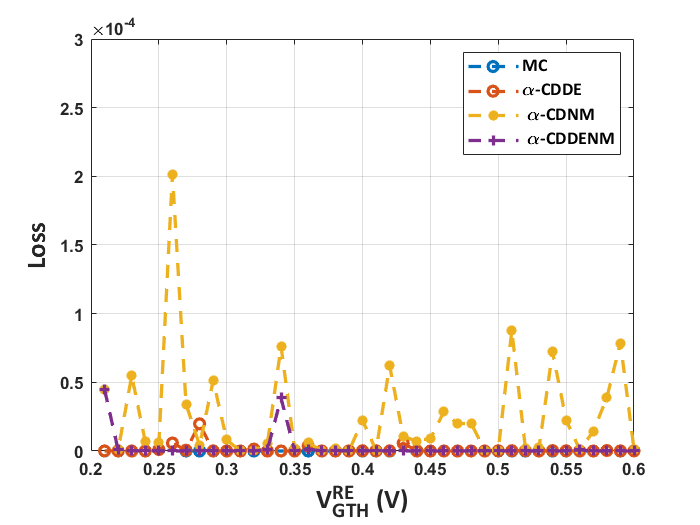

set(hh,'FontName','Calibri','FontSize',11,'FontWeight','bold')
grid on
fig=gcf;
%fig.PaperPosition = 'auto';
fig_pos=fig.PaperPosition;
fig.PaperSize=[fig_pos(3),fig_pos(4)];
saveas(gcf,'vgthid-loss.pdf')

figure(10)
BestCost_nm(BestCost_nm==0)=100;
BestCost(BestCost==0)=100;
BestCost_denm(BestCost_denm==0)=100;
loss_mc=zeros(40,1);
loss_de=zeros(40,1);
loss_nm=zeros(40,1);
loss_denm=zeros(40,1);
jj=1:40;
vgthre1=0.01*jj+0.2;
for jj=1:40
    minloss=abs(min(BestCost_mc(:,jj,:)));
    loss_mc(jj)=minloss(1);
    minloss=min(BestCost_nm(:,jj,:));
    loss_nm(jj)=minloss(1);
    minloss=min(BestCost(:,jj,:));
    loss_de(jj)=minloss(1);
    minloss=min(BestCost_denm(:,jj,:));
    loss_denm(jj)=minloss(1);
end
subplot(121)
loss_de(loss_de>3e-5)=0;
p = polyfit(vgthre1, loss_mc', 2); % 进行二次拟合，获取多项式系数
yy_mc = polyval(p, vgthre1); % 计算拟合曲线的纵坐标
p = polyfit(vgthre1, loss_de', 2); % 进行二次拟合，获取多项式系数
yy_de = polyval(p, vgthre1); % 计算拟合曲线的纵坐标
p = polyfit(vgthre1, loss_nm', 2); % 进行二次拟合，获取多项式系数
yy_nm = polyval(p, vgthre1); % 计算拟合曲线的纵坐标
p =polyfit(vgthre1, loss_denm', 2); % 进行二次拟合，获取多项式系数
yy_denm = polyval(p, vgthre1); % 计算拟合曲线的纵坐标
plot(vgthre1(1:1:40),yy_mc(1:1:40)','--o','LineWidth',2);
hold on
plot(vgthre1(1:1:40),yy_de(1:1:40)','--o','LineWidth',2);
plot(vgthre1(1:1:40),yy_nm(1:1:40)','--*','LineWidth',2);
plot(vgthre1(1:1:40),yy_denm(1:1:40)','--+','LineWidth',2);
xlabel('\fontname{Calibri}\fontsize{16}V_{GTH}^{RE} (V)','FontWeight','bold')
ylabel('\fontname{Calibri}\fontsize{16}Loss','FontWeight','bold')
%ylim([0 1e-5])
set(gca, 'FontWeight', 'bold');
hh=legend('MC', '\alpha-CDDE',' \alpha-CDNM',' \alpha-CDDENM')

hh =   Legend (MC, \alpha-CDDE,  \alpha-CDNM,  \alpha-CDDENM) - 属性:

         String: {'MC'  '\alpha-CDDE'  ' \alpha-CDNM'  ' \alpha-CDDENM'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 8.1000
       Position: [0.2483 0.7577 0.2025 0.1426]
          Units: 'normalized'

  显示 所有属性


set(hh,'FontName','Calibri','FontSize',11,'FontWeight','bold')
grid on
subplot(122)
plot(vgthre1(1:1:40),yy_de(1:1:40)','--o','LineWidth',2);
hold on
plot(vgthre1(1:1:40),yy_nm(1:1:40)','--*','LineWidth',2);
plot(vgthre1(1:1:40),yy_denm(1:1:40)','--+','LineWidth',2);
xlabel('\fontname{Calibri}\fontsize{16}V_{GTH}^{RE} (V)','FontWeight','bold')
ylabel('\fontname{Calibri}\fontsize{16}Loss','FontWeight','bold')
%ylim([0 1e-5])
set(gca, 'FontWeight', 'bold');
hh=legend('\alpha-CDDE',' \alpha-CDNM',' \alpha-CDDENM')

hh =   Legend (\alpha-CDDE,  \alpha-CDNM,  \alpha-CDDENM) - 属性:

         String: {'\alpha-CDDE'  ' \alpha-CDNM'  ' \alpha-CDDENM'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 8.1000
       Position: [0.6897 0.7913 0.2025 0.1090]
          Units: 'normalized'

  显示 所有属性


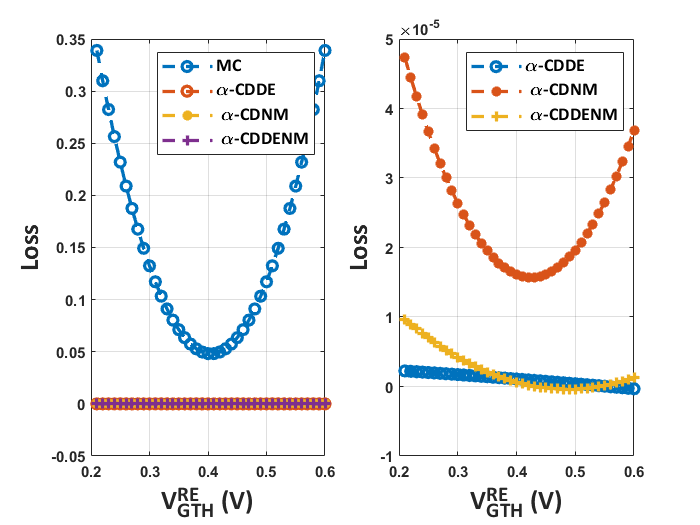

set(hh,'FontName','Calibri','FontSize',11,'FontWeight','bold')
grid on
fig=gcf;
%fig.PaperPosition = 'auto';
fig_pos=fig.PaperPosition;
fig.PaperSize=[fig_pos(3),fig_pos(4)];
saveas(gcf,'vgthid-loss2.pdf')

3.5 柱状图表示

% figure(6)
% jj=1:4:40;
% vgthre1=0.01*jj+0.2;
% bar1(1:10,1) = (loss_de(1:4:40)');
% bar1(1:10,2) = (loss_nm(1:4:40)');
% bar1(1:10,3) = (loss_denm(1:4:40)');
% GO = bar(bar1,1,'EdgeColor','black');%边框颜色为黑色
% % GO(1).FaceColor = [0/255,0/255,255/255];%设置第一个柱状图的颜色
% % GO(2).FaceColor = [70/255,112/255,80/255];%设置第2个柱状图的颜色
% % GO(2).FaceColor = [112/255,128/255,144/255];%设置第3个柱状图的颜色
% %ylim([2000 3000])                              %y轴显示的范围，根据需要调整
% % 图例
% legend({'\alpha-CDDE','\alpha-CDNM',' \alpha-CDDENM'},'FontName','Calibri','fontsize',11);
% set(gca,'Xticklabel', vgthre1,'fontweight','bold')  %gca 坐标的句柄
% %set(gca,'xtick',0.2:0.04:0.6)
% xlabel('\fontname{Calibri}\fontsize{16}V_{GTH}^{RE} (V)','FontWeight','bold')
% ylabel('\fontname{Calibri}\fontsize{16}Loss','FontWeight','bold')
% grid on
% set(gca, 'FontWeight', 'bold');
% set(gca, 'YScale','log');
% %end
% fig=gcf;
% %fig.PaperPosition = 'auto';
% fig_pos=fig.PaperPosition;
% fig.PaperSize=[fig_pos(3),fig_pos(4)];
% saveas(gcf,'vgthid-loss.pdf')

4. 对于不同$V_{\mathrm{GTH}}^{\mathrm{RE}}$,两种算法的时间表现

% figure(4)
% tt_de=zeros(40,1);
% tt_nm=zeros(40,1);
% jj=1:40;
% vgthid=0.01*jj+0.2;
% for ii=3:3
% plot(vgthid,t_de(ii,:),'--','LineWidth',2);
% hold on
% plot(vgthid,t_nm(ii,:));
% end
% grid on
% xlabel('\fontname{Calibri}\fontsize{16}V_{GTH}^{RE} (V)')
% ylabel('\fontname{Calibri}\fontsize{16}T (s)')
% fig=gcf;
% %fig.PaperPosition = 'auto';
% fig_pos=fig.PaperPosition;
% fig.PaperSize=[fig_pos(3),fig_pos(4)];
% saveas(gcf,'vgthid-t.pdf')

5柱状图

% figure(5)
% x = 1:1:10; %第一个1是起始端点，中间的是步长，最后一个是结束端点
% 
% %纵坐标
% % for ii=1:4
% ii=3;
% jj=1:4:40;
% vgthre1=0.01*jj+0.2;
% num=410+ii;
% t_nm(ii+4,20:32)=t_nm(ii+4,20:32)*10;
% %subplot(num)
% figure(ii+10)
% bar2(1:10,1) = t_de(ii+4,jj)';
% bar2(1:10,2) = t_nm(ii+4,jj)';
% bar2(1:10,3) = t_denm(ii+4,jj)';
% bar2(1:10,4) = t_mc(ii+4,jj)';
% GO = bar(bar2,1,'EdgeColor','black');%边框颜色为黑色
% % GO(1).FaceColor = [0/255,0/255,255/255];%设置第一个柱状图的颜色
% % GO(2).FaceColor = [255/255,255/255,0/255];%设置第2个柱状图的颜色
% % GO(2).FaceColor = [112/255,128/255,144/255];%设置第3个柱状图的颜色
% %ylim([2000 3000])                              %y轴显示的范围，根据需要调整
% % 图例
% legend({'\alpha-CDDE','\alpha-CDNM',' \alpha-CDDENM','MC'},'FontName','Calibri','fontsize',11);
% set(gca,'Xticklabel', vgthre1,'fontweight','bold')  %gca 坐标的句柄
% set(gca,'ytick',0:0.1:2)
% xlabel('\fontname{Calibri}\fontsize{16}V_{GTH}^{RE} (V)','FontWeight','bold')
% ylabel('\fontname{Calibri}\fontsize{16}Running Time (s)','FontWeight','bold')
% grid on
% set(gca, 'FontWeight', 'bold');
% %end
% fig=gcf;
% %fig.PaperPosition = 'auto';
% fig_pos=fig.PaperPosition;
% fig.PaperSize=[fig_pos(3),fig_pos(4)];
% saveas(gcf,'vgthid-run-time.pdf')


全局参数

global VDD VTH alp_p  fclk ceq gnd ag  gpu beta_m ku kd vgthid
VDD=1.2;
alp_p=0.5;
fclk=500e6;
beta_m=1.4;
m=3;
H=[1.40E+00	1.40E+00	1.40E+00	1.40E+00	1.40E+00	1.40E+00	1.40E+00]'*1e-6;
W=[8.00E-01	1.00E+00	1.40E+00	8.00E-01	1.00E+00	1.40E+00	6.00E-01]'*1e-6;
trs=[2.86E-02	4.96E-02	7.45E-02	1.71E-02	1.96E-02	2.20E-02	1.39E-02]'*1e-9;
tfs=[1.44E-02	1.66E-02	1.80E-02	2.33E-02	3.75E-02	5.47E-02	1.24E-02]'*1e-9;
Ih=[1.79E+02	2.69E+02	3.59E+02	5.09E+01	3.57E+01	2.80E+01	8.98E+01]'*1e-6;
Il=[2.08E+01	3.12E+01	4.16E+01	2.71E+00	1.50E+00	1.06E+00	1.04E+01]'*1e-6;
tp=(trs+tfs)/2;
req=VDD./(Il+Ih);
geq=(Il+Ih)/VDD;
ag=H.*W;
cin=tp./req;
geqp=cin./trs;
geqn=cin./tfs;
ceq=cin;
gnd=geqn;
gpu=geqp;
kd=[0.5	0.33	0.25	4	3	2	1]';
ku=[2	3	4	0.25	0.33	0.5	1]';

VTH=0.335;
etamax=0.1;
taomax=0.2e-9;
vgthid=0.5;
eta1=((VDD-VTH)/(sqrt(etamax)+vgthid-VTH))^2*kd'-beta_m*ku';
eta2=-((VDD-VTH)/(-sqrt(etamax)+vgthid-VTH))^2*kd'+beta_m*ku';
tao1=0.345*ceq'-taomax*geqp';
tao2=0.345*ceq'-taomax*geqn';

tp

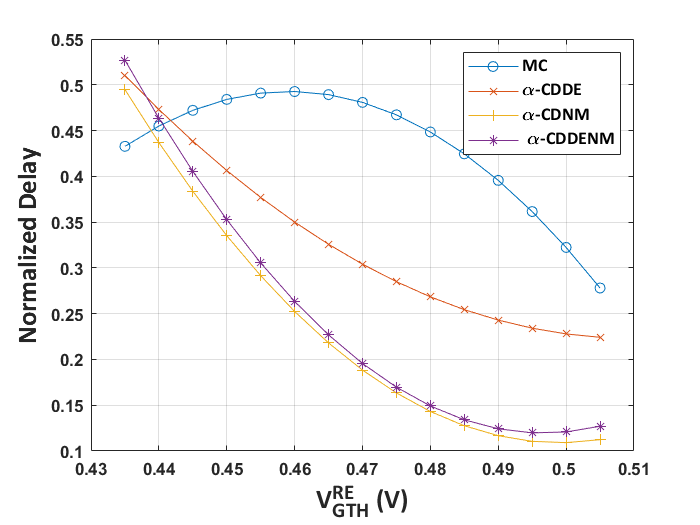

BestCost_nm(BestCost_nm==0)=100;
BestCost(BestCost==0)=100;
loss_de=zeros(40,1);
loss_nm=zeros(40,1);
jj=1:40;
%vgthre1=0.01*jj+0.2;
tp_mc=zeros(10,40);
tphl_mc=zeros(10,40);
tplh_mc=zeros(10,40);
tp_nm=zeros(10,40);
tphl_nm=zeros(10,40);
tplh_nm=zeros(10,40);
tp_de=zeros(10,40);
tphl_de=zeros(10,40);
tplh_de=zeros(10,40);
tp_denm=zeros(10,40);
tphl_denm=zeros(10,40);
tplh_denm=zeros(10,40);
for ii=5:5
    for jj=1:40
        if BestPosition_nm(ii,jj,:)==zeros(1,1,7)
            %             tp_nm(ii,jj)=inf;
            %             tphl_nm(ii,jj)=inf;
            %             tplh_nm(ii,jj)=inf;
            %         elseif BestPosition(ii,jj,:)==zeros(1,1,7)
            %             tp_de(ii,jj)=inf;
            %             tphl_de(ii,jj)=inf;
            %             tplh_de(ii,jj)=inf;
        else
            tp_mc(ii,jj)=gettp(reshape(BestPosition_mc(ii,jj,:),[7,1]));
            tp_nm(ii,jj)=gettp(reshape(BestPosition_nm(ii,jj,:),[7,1]));
            % tphl_nm(ii,jj)=gettphl(reshape(BestPosition_nm(ii,jj,:),[7,1])');
            % tplh_nm(ii,jj)=gettplh(reshape(BestPosition_nm(ii,jj,:),[7,1])');
            tp_de(ii,jj)=gettp(reshape(BestPosition(ii,jj,:),[7,1]));
            tp_denm(ii,jj)=gettp(reshape(BestPosition_denm(ii,jj,:),[7,1]));
            % tphl_de(ii,jj)=gettphl(reshape(BestPosition(ii,jj,:),[7,1])');
            %tplh_de(ii,jj)=gettplh(reshape(BestPosition(ii,jj,:),[7,1])');
        end
    end
    figure(ii+20)
    maxtp=max([max(tp_nm(ii,1:40)),max(tp_de(ii,1:40)),...
        max(tp_de(ii,1:40)),max(tp_denm(ii,1:40)),max(tp_mc(ii,1:40))]);
    mintp=min([min(tp_nm(ii,1:40)),min(tp_de(ii,1:40)),...
        min(tp_de(ii,1:40)),min(tp_denm(ii,1:40)),max(tp_mc(ii,1:40))]);
    dtp=maxtp-mintp;
%     dtp_mc=max(tp_mc(ii,1:40))-min(tp_mc(ii,1:40));
%     dtp_nm=max(tp_nm(ii,1:40))-min(tp_nm(ii,1:40));
%     dtp_de=max(tp_de(ii,1:40))-min(tp_de(ii,1:40));
%     dtp_denm=max(tp_denm(ii,1:40))-min(tp_denm(ii,1:40));
    %     plot(vgthre1(1:40),(tp_nm(ii,1:40)-min(tp_nm(ii,1:40)))/dtp_nm,'--o','LineWidth',2);
    %     hold on
    %     plot(vgthre1(1:40),(tp_de(ii,1:40)-min(tp_de(ii,1:40)))/dtp_de,'--*','LineWidth',2);
    %     plot(vgthre1(1:40),(tp_denm(ii,1:40)-min(tp_denm(ii,1:40)))/dtp_denm,'--+','LineWidth',2);
    %     xlabel('\fontname{Calibri}\fontsize{16}V_{GTH}^{RE} (V)','FontWeight','bold')
    %     ylabel('\fontname{Calibri}\fontsize{16}Normalized Delay','FontWeight','bold')
    %     hh=legend(' \alpha-CDDE',' \alpha-CDNM',' \alpha-CDDENM');
    %     set(hh,'FontName','Calibri','FontSize',11,'FontWeight','bold')
    %     grid on
    jj=23:1:37;
    vgthre1=0.01*jj+0.2;
    loss_tp_mc=(tp_mc(ii,1:40)-mintp)/dtp;
    loss_tp_nm=(tp_nm(ii,1:40)-mintp)/dtp;
    loss_tp_de=(tp_de(ii,1:40)-mintp)/dtp;
    loss_tp_denm=(tp_denm(ii,1:40)-mintp)/dtp;
    p = polyfit(vgthre1, loss_tp_mc(23:1:37), 2); % 进行二次拟合，获取多项式系数
    yy_mc = polyval(p, vgthre1); % 计算拟合曲线的纵坐标
    p = polyfit(vgthre1, loss_tp_de(23:1:37), 2); % 进行二次拟合，获取多项式系数
    yy_de = polyval(p, vgthre1); % 计算拟合曲线的纵坐标
    p = polyfit(vgthre1, loss_tp_nm(23:1:37), 2); % 进行二次拟合，获取多项式系数
    yy_nm = polyval(p, vgthre1); % 计算拟合曲线的纵坐标
    p =polyfit(vgthre1, loss_tp_denm(23:1:37), 2); % 进行二次拟合，获取多项式系数
    yy_denm = polyval(p, vgthre1); % 计算拟合曲线的纵坐标
    plot(vgthre1, yy_mc,'-o') % 绘制数据点和拟合曲线
    hold on
    plot(vgthre1, yy_de,'-x') % 绘制数据点和拟合曲线
    
    plot(vgthre1, yy_nm,'-+') % 绘制数据点和拟合曲线
    plot(vgthre1, yy_denm,'-*') % 绘制数据点和拟合曲线
    %     bar1(1:15,1) = (loss_tp_de(23:1:37)');
%     bar1(1:15,2) = (loss_tp_nm(23:1:37)');
%     bar1(1:15,3) = (loss_tp_denm(23:1:37)');
%     GO = bar(bar1,1,'EdgeColor','black');%边框颜色为黑色                              %y轴显示的范围，根据需要调整
    % 图例
    grid on
    legend({'MC','\alpha-CDDE','\alpha-CDNM',' \alpha-CDDENM'},'FontName','Calibri','fontsize',11);
    set(gca,'Xticklabel', vgthre1,'fontweight','bold')  %gca 坐标的句柄
    xlabel('\fontname{Calibri}\fontsize{16}V_{GTH}^{RE} (V)','FontWeight','bold')
    ylabel('\fontname{Calibri}\fontsize{16}Normalized Delay','FontWeight','bold')
    grid on
    set(gca, 'FontWeight', 'bold');
    %set(gca, 'YScale','log');
end
%set(gca, 'FontWeight', 'bold');
fig=gcf;
%fig.PaperPosition = 'auto';
fig_pos=fig.PaperPosition;
fig.PaperSize=[fig_pos(3),fig_pos(4)];
saveas(gcf,'vgthre-tp.pdf')

Pt

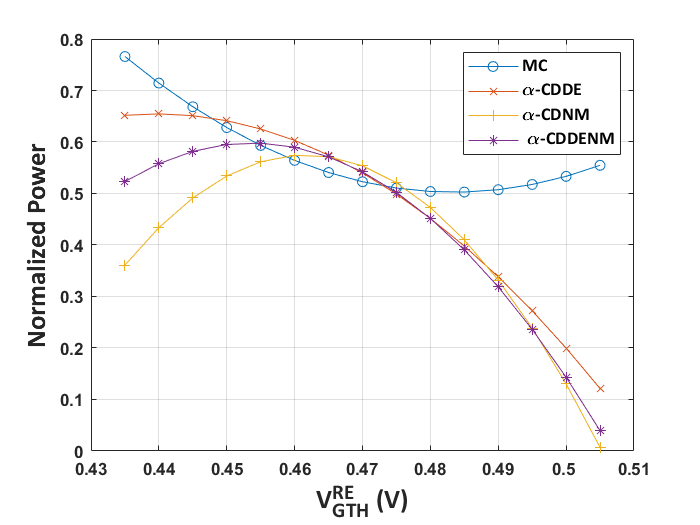

%BestCost_nm(BestCost_nm==0)=100;
%BestCost(BestCost==0)=100;
jj=1:40;
vgthre1=0.01*jj+0.2;
pw_nm=zeros(10,40);
pw_de=zeros(10,40);
pw_denm=zeros(10,40);
pw_mc=zeros(10,40);
for ii=5:5
    for jj=1:40
        %        if BestPosition_nm(ii,jj,:)==zeros(1,1,7)
        %             pw_nm(ii,jj)=inf;
        %         elseif BestPosition(ii,jj,:)==zeros(1,1,7)
        %             pw_de(ii,jj)=inf;
        %         if BestPosition_denm(ii,jj,:)==zeros(1,1,7)
        %             temp1=pw_nm(ii,jj);
        %             temp2=pw_de(ii,jj);
        %             pw_denm(ii,jj)=min(temp1,temp2);
        %
        %         else
        pw_nm(ii,jj)=getpw(reshape(BestPosition_nm(ii,jj,:),[7,1]));
        pw_mc(ii,jj)=getpw(reshape(BestPosition_mc(ii,jj,:),[7,1]));
        % tphl_nm(ii,jj)=gettphl(reshape(BestPosition_nm(ii,jj,:),[7,1])');
        % tplh_nm(ii,jj)=gettplh(reshape(BestPosition_nm(ii,jj,:),[7,1])');
        pw_de(ii,jj)=getpw(reshape(BestPosition(ii,jj,:),[7,1]));
        pw_denm(ii,jj)=getpw(reshape(BestPosition_denm(ii,jj,:),[7,1]));
        % tphl_de(ii,jj)=gettphl(reshape(BestPosition(ii,jj,:),[7,1])');
        %tplh_de(ii,jj)=gettplh(reshape(BestPosition(ii,jj,:),[7,1])');
        %         end
    end
    figure(ii+30)
    maxpw=max([max(pw_nm(ii,1:40)),max(pw_de(ii,1:40)),...
        max(pw_de(ii,1:40)),max(pw_denm(ii,1:40)),max(pw_mc(ii,1:40))]);
    minpw=min([min(pw_nm(ii,1:40)),min(pw_de(ii,1:40)),...
        min(pw_de(ii,1:40)),min(pw_denm(ii,1:40)),max(pw_mc(ii,1:40))]);    
    dpw=maxpw-minpw;
%     dpw_nm=max(pw_nm(ii,1:40))-min(pw_nm(ii,1:40));
%     dpw_de=max(pw_de(ii,1:40))-min(pw_de(ii,1:40));
%     dpw_denm-min(pw_denm(ii,1:40));
%     dpw_mc=max(pw_mc(ii,1:40))-min(pw_mc(ii,1:40));
%     plot(vgthre1(1:40),pw_nm(ii,1:40)/dpw_nm,'--o','LineWidth',2);
%     hold on
%     plot(vgthre1(1:40),pw_de(ii,1:40)/dpw_de,'--*','LineWidth',2);
%     plot(vgthre1(1:40),pw_denm(ii,1:40)/dpw_denm,'--+','LineWidth',2);
%     xlabel('\fontname{Calibri}\fontsize{16}V_{GTH}^{RE} (V)','FontWeight','bold')
%     ylabel('\fontname{Calibri}\fontsize{16}Normalized Power','FontWeight','bold')
%     hh=legend(' \alpha-CDDE',' \alpha-CDNM',' \alpha-CDDENM');
%     set(hh,'FontName','Calibri','FontSize',11,'FontWeight','bold')
%     grid on
    jj=23:1:37;
    vgthre1=0.01*jj+0.2;
    loss_pw_nm=(pw_nm(ii,1:40)-minpw)/dpw;
    loss_pw_mc=(pw_mc(ii,1:40)-minpw)/dpw;
    loss_pw_de=(pw_de(ii,1:40)-minpw)/dpw;
    loss_pw_denm=(pw_denm(ii,1:40)-minpw)/dpw;
    p = polyfit(vgthre1, loss_pw_de(23:1:37), 2); % 进行二次拟合，获取多项式系数
    yy_de = polyval(p, vgthre1); % 计算拟合曲线的纵坐标
     p = polyfit(vgthre1, loss_pw_mc(23:1:37), 2); % 进行二次拟合，获取多项式系数
    yy_mc = polyval(p, vgthre1); % 计算拟合曲线的纵坐标
    p = polyfit(vgthre1, loss_pw_nm(23:1:37), 2); % 进行二次拟合，获取多项式系数
    yy_nm = polyval(p, vgthre1); % 计算拟合曲线的纵坐标
    p =polyfit(vgthre1, loss_pw_denm(23:1:37), 2); % 进行二次拟合，获取多项式系数
    yy_denm = polyval(p, vgthre1); % 计算拟合曲线的纵坐标
    plot(vgthre1, yy_mc,'-o') % 绘制数据点和拟合曲线
    hold on
    plot(vgthre1, yy_de,'-x') % 绘制数据点和拟合曲线
    plot(vgthre1, yy_nm,'-+') % 绘制数据点和拟合曲线
    plot(vgthre1, yy_denm,'-*') % 绘制数据点和拟合曲线
%     bar1(1:15,1) = (loss_pw_de(23:1:37)');
%     bar1(1:15,2) = (loss_pw_nm(23:1:37)');
%     bar1(1:15,3) = (loss_pw_denm(23:1:37)');
%     GO = bar(bar1,1,'EdgeColor','black');%边框颜色为黑色                              %y轴显示的范围，根据需要调整
%     % 图例
    legend({'MC','\alpha-CDDE','\alpha-CDNM',' \alpha-CDDENM'},'FontName','Calibri','fontsize',11);
    set(gca,'Xticklabel', vgthre1,'fontweight','bold')  %gca 坐标的句柄
    xlabel('\fontname{Calibri}\fontsize{16}V_{GTH}^{RE} (V)','FontWeight','bold')
    ylabel('\fontname{Calibri}\fontsize{16}Normalized Power','FontWeight','bold')
    grid on
    set(gca, 'FontWeight', 'bold');
    
end
set(gca, 'FontWeight', 'bold');
fig=gcf;
%fig.PaperPosition = 'auto';
fig_pos=fig.PaperPosition;
fig.PaperSize=[fig_pos(3),fig_pos(4)];
saveas(gcf,'vgthre-pw.pdf')

多比较器算法验证 0.2~0.84

% % 使用sort()函数将A从大到小排序
% [sortedA, idx] = sort(, 'descend');
% % 提取前20个最大的数及其索引
% top20 = sortedA(1:20);
% top20_idx = idx(1:20);